### Loading dataset

dpath = 'restaurantLab_ExtMR.xlsx'; % dataset path

T = readtable(dpath, 'ReadVariableNames',true, 'ReadRowNames',true);

[n, p] = size(T); % n = no of rows, p = no of columns

Converting categorical variables.

T.DayType = categorical(T.DayType, 'Ordinal', true);
T.Area = categorical(T.Area, 'Ordinal', true);

#### Plotting Daily Sales

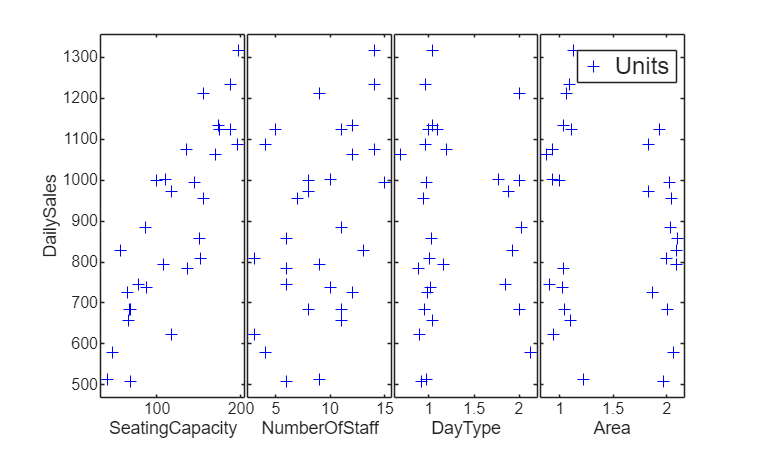

yXplot(T(:, "DailySales"), T(:, 2:end));

The yXplot shows that the **SeatingCapicity** has the strongest relationship with **DailySales**, which obviously means bigger outlets make more daily sales than small ones. Moreover, it does not illustrate a lot of Area and DayType.

### Full Multiple Regression Model

% fitting the model
mdl = fitlm(T, "DailySales");

disp(mdl); % model summary


Linear regression model:
    DailySales ~ 1 + SeatingCapacity + NumberOfStaff + DayType + Area

Estimated Coefficients:
                       Estimate      SE        tStat        pValue  
                       ________    _______    ________    __________

    (Intercept)         118.19       43.82      2.6971      0.012342
    SeatingCapacity     4.3516     0.22473      19.363    1.4485e-16
    NumberOfStaff       22.671      2.9024      7.8113    3.6207e-08
    DayType_weekend     178.17      23.486      7.5863    6.1006e-08
    Area_suburb        -19.295      20.026    -0.96348       0.34454


Number of observations: 30, Error degrees of freedom: 25
Root Mean Squared Error: 53.8
R-squared: 0.949,  Adjusted R-Squared: 0.941
F-statistic vs. constant model: 117, p-v

All other predictors statistically significant except the Area. Because, the p-value > 0.05 of Area for suburb.

#### Removing insignificant variables

% remove Area
mdl1 = removeTerms(mdl, "Area");

disp(mdl1); % new model summary


Linear regression model:
    DailySales ~ 1 + SeatingCapacity + NumberOfStaff + DayType

Estimated Coefficients:
                       Estimate      SE       tStat       pValue  
                       ________    _______    ______    __________

    (Intercept)         102.22      40.511    2.5233      0.018076
    SeatingCapacity     4.3785     0.22269    19.662     3.947e-17
    NumberOfStaff       23.019      2.8759    8.0042    1.7518e-08
    DayType_weekend     180.13      23.365    7.7096    3.5129e-08


Number of observations: 30, Error degrees of freedom: 26
Root Mean Squared Error: 53.7
R-squared: 0.947,  Adjusted R-Squared: 0.941
F-statistic vs. constant model: 156, p-value = 9.93e-17


Even after removing **Area** variables the model still explains the sales well. The model illustrates, an **Outlet** on a weekday with average **Seating Capacity** and typical **number of staff** produce sales of roughly **102** meals. However, on **+1** increase of seating capacity increases sales by **4** four additonal sales. And increasing the staff by **+1** will increase sales with **+23** more.

#### Testing Joint Hypothesis

% Define the restrictions for the coefficients
C = zeros(2, 4);

C(1, 2) = 1; % beta_noOfStaff
C(2, 3) = 1; % beta_dayType

[pVal, fTest] = coefTest(mdl1, C);

% Display the p-value and F-test statistic
fprintf('p-value: %.16f \nF-test statistic: %.4f\n', [pVal, fTest]);

p-value: 0.0000000000000000 
F-test statistic: 233.2459


The p-value is extremely small and F-statistics is around 233 which clearly explains that they are strongly significant.

### Stepwise Selection and Comparison

This method automatically select a subset of independent variables that optimally predict the dependent variable.

swMdl = stepwiselm(T, "DailySales");

1. Adding SeatingCapacity, FStat = 69.2876, pValue = 4.67646e-09
2. Adding NumberOfStaff, FStat = 17.851, pValue = 0.000243432
3. Adding DayType, FStat = 59.4385, pValue = 3.51295e-08


The **stepwise model** and the **reduced model** are completely identical with each other.

#### Plotting deletion (studentized) **residuals** against fitted values

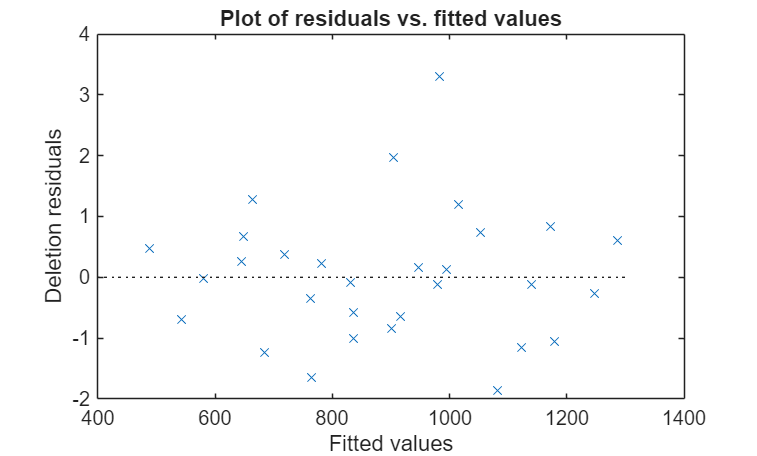

close all; % just to prevent plotting errors (haha)

plotResiduals(mdl1, "fitted", "ResidualType","studentized");
xlabel('Fitted values');
ylabel('Deletion residuals');

There is a **curvature** shape made by data points with rare outliers. Most of them are in range of **-1 to 2**, they are not outliers.

### Model Prediction

% to predict daily sales we need,
% 1. seating capacity; 2. no of staff; 3. day type;

x0 = T(3, 2:4); % we used T, just for labels and making it a table
x0.SeatingCapacity = 160;
x0.NumberOfStaff = 8;
x0.DayType = "weekend";

% Predict daily sales using the fitted model
[predictedSales, predCI] = predict(mdl1, x0, 'Alpha', 0.01, ...
    'Prediction', 'Observation');

fprintf('Predicted Daily Sales: %.2f\n', predictedSales);

Predicted Daily Sales: 1167.06


fprintf('99 per cent pediction Confidence Interval:\n [%.4f, %.4f]\n', predCI(1), predCI(2));

99 per cent pediction Confidence Interval:
 [1003.8532, 1330.2679]
